# SISO Analysis and Control Design

## 3. SISO Control Design for Reference Tracking

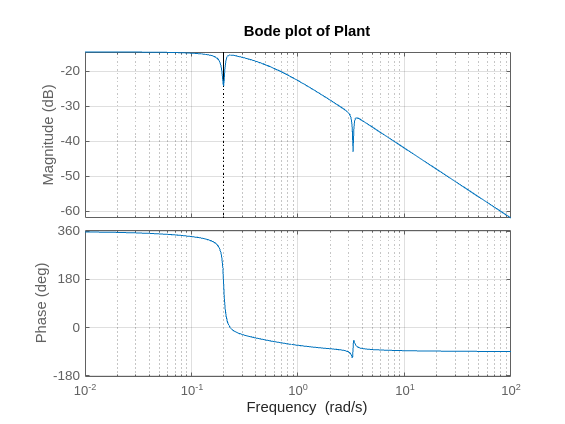

load statespace_data A B C D FWT

% SISO: only first input, only first column of B
BSISO = B(:,1);
DSISO = 0;
CSISO = C(1,:);

s = tf('s');

SISOsys = -ss(A, BSISO, CSISO, DSISO);

figure
margin(SISOsys)
title('Bode plot of Plant')
grid on

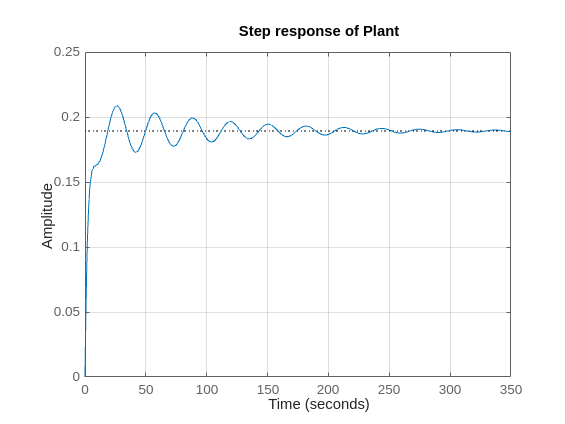


% SISO TF
[b, a] = ss2tf(A, BSISO, CSISO, DSISO);
SISO_G = -tf(b, a);

figure 
step(SISOsys)
grid on
title('Step response of Plant')


stepinfo(SISOsys)

ans = struct with fields:
         RiseTime: 13.6517
    TransientTime: 168.7029
     SettlingTime: 168.7029
      SettlingMin: 0.1704
      SettlingMax: 0.2086
        Overshoot: 10.2142
       Undershoot: 0
             Peak: 0.2086
         PeakTime: 26.4813


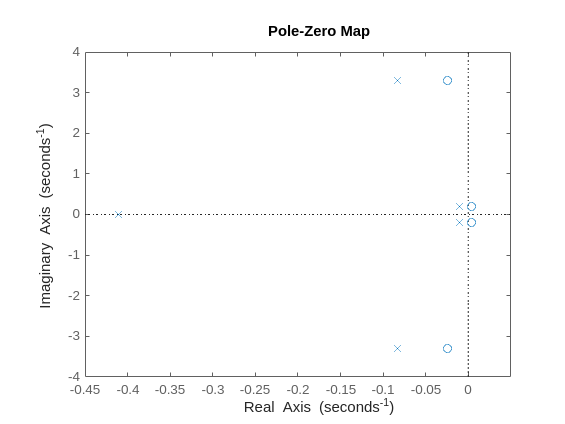


figure
pzmap(SISO_G)

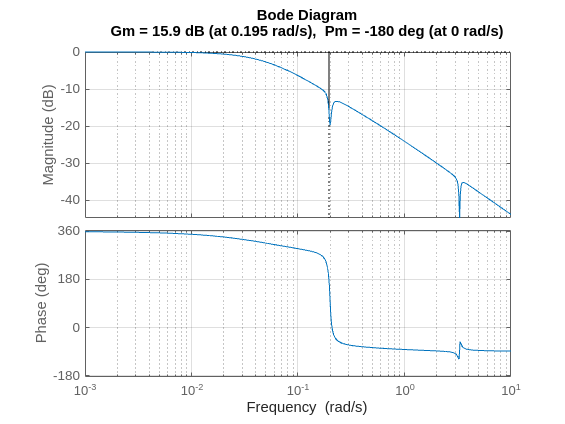


SISO_poles = pole(SISO_G);
SISO_zeros = zero(SISO_G);

[Gm, Pm, Wcg, Wcp] = margin(SISO_G);
Kp = 0.8;
Ki = 0.28;
Kd = 0;
SISO_C = pid(Kp,Ki,Kd);

%pidTuner(SISO_G, 'PI')

SISO_CL = getPIDLoopResponse(SISO_C, SISO_G, 'closed-loop');

figure
margin(SISO_CL)
%title('Bode Plot of Closed-Loop')
grid on

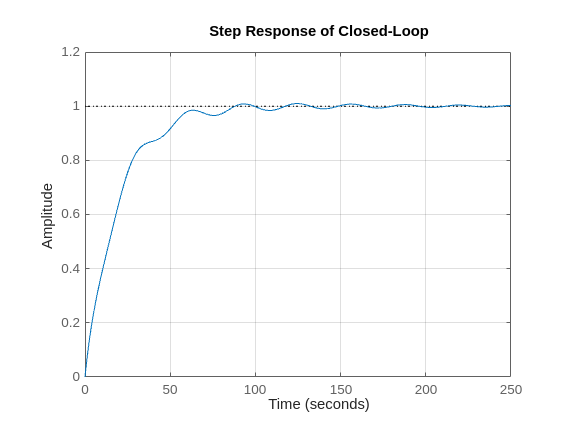


figure
step(SISO_CL)
title('Step Response of Closed-Loop')
grid on 


stepinfo(SISO_CL)

ans = struct with fields:
         RiseTime: 45.7899
    TransientTime: 82.5870
     SettlingTime: 82.5870
      SettlingMin: 0.9033
      SettlingMax: 1.0097
        Overshoot: 0.9741
       Undershoot: 0
             Peak: 1.0097
         PeakTime: 124.5226


## 4. SISO Control Design for Disturbance Rejection

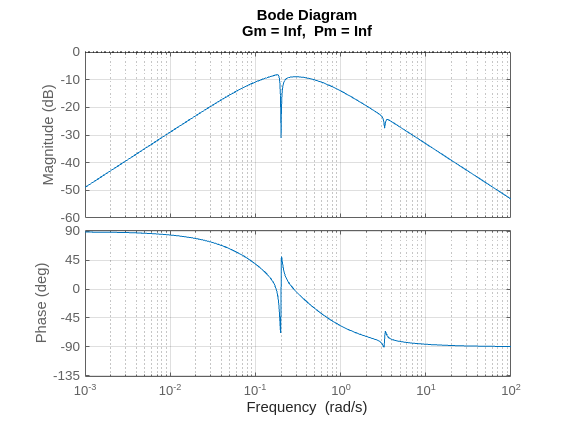

% SISO: only disturbance, only third column of B
Bd = B(:,3);

% SISO disturbance TF
[bd, ad] = ss2tf(A, Bd, CSISO, DSISO);
SISO_G_dis = tf(bd, ad);

% Ref tracker on Disturbance input
SISO_CL_dis = getPIDLoopResponse(SISO_C, SISO_G_dis, 'input-disturbance');

figure
margin(SISO_CL_dis)
grid on

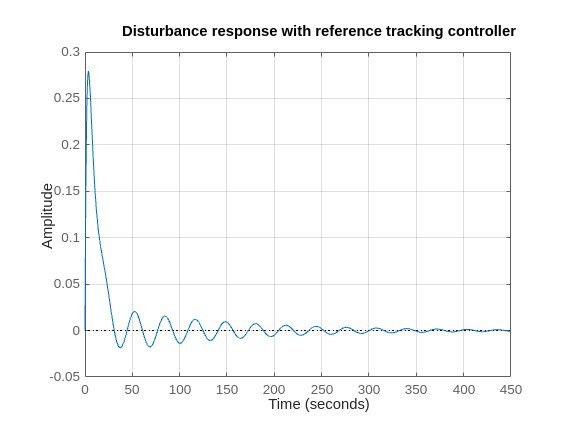


figure
step(SISO_CL_dis)
title('Disturbance response with reference tracking controller')
grid on 

# Multi-variable Mixed Sensitivity

## 1. Computing RGA

w0 = 0;
w1 = 0.2*3*pi;

% Define plant and in and outputs
MIMO_G = FWT(1:2, 1:2);
MIMO_G.u = 'u';
MIMO_G.y = 'y';

% Calculate RGA
Gw0 = freqresp(MIMO_G, w0);
Gw1 = freqresp(MIMO_G, w1);

RGAw0 = Gw0.*pinv(Gw0).'

RGAw0 =    -0.6554    1.6554
    1.6554   -0.6554


RGAw1 = Gw1.*pinv(Gw1).'

RGAw1 =   -0.0283 + 0.1398i   1.0283 - 0.1398i
   1.0283 - 0.1398i  -0.0283 + 0.1398i


## 2. MIMO Poles and Zeros

% MIMO poles and zeros 
MIMO_poles = pole(MIMO_G)

MIMO_poles =   -0.0832 + 3.2936i
  -0.0832 - 3.2936i
  -0.4104 + 0.0000i
  -0.0106 + 0.2022i
  -0.0106 - 0.2022i


MIMO_zeros = zero(MIMO_G)

MIMO_zeros =   -0.0078 + 1.2358i
  -0.0078 - 1.2358i


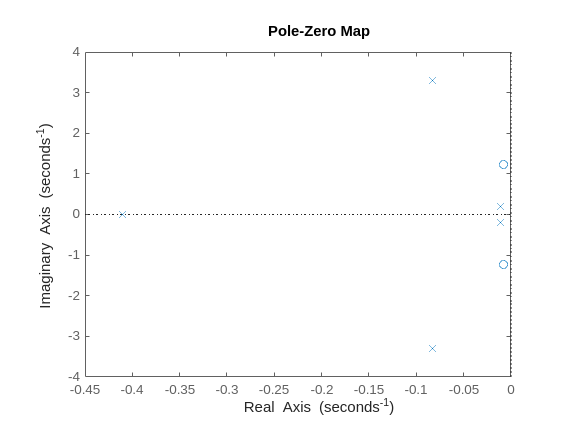


figure
pzmap(MIMO_G)

## 3. $W_p$

% Computing wp11

f_co = 0.3; % cut-off = bandwidth

wp = [(s/3+0.3*2*pi)/(s+pi*6e-5) 0;
    0 0.05];
wp.u = 'v';
wp.y = 'z1';

## 5. Generalised Plant

% Wu given
wu = [0.005 0;
       0 (0.005*s^2 + 0.0007*s+0.00005)/(s^2 + 0.0014*s + 10^(-6))];
wu.u = 'u';
wu.y = 'z2';

% Build system
sumblock = sumblk("v = w + y", 2);

P = connect(MIMO_G, wu, wp, sumblock, {'w', 'u'}, {'z1', 'z2', 'v'});

## 7. Mixed-Sensitivity Generalised Controller

% H infinity synthesis
nmeas = 2; %number of outputs of plant = number of inputs controller
ncont = 2; 
[MS_C,CLms,gamma] = hinfsyn(P,nmeas,ncont);

MS_C.u = 'v';
MS_C.y = 'u';

ol = MS_C*MIMO_G

ol =
 
  A = 
                            ?             ?             ?             ?             ?             ?             ?             ?  Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)
   ?                   -29.04         23.36        0.8346         1.528         1.288      -0.01752        -2.251        -105.6     2.569e-13             0      1.03e-14             0      1.03e-14
   ?                   -2.342         1.882        0.0157        0.1339        0.1069     -0.001976       -0.2198        -8.741    -7.253e-13             0     -2.82e-13             0     -2.82e-13
   ?               -2.378e-12             1    -1.978e-12     1.128e-13    -1.872e-12    -1.346e-15     -1.79e-13    -7.897e-12     4.905e-13             0     2.033e-12             0     2.033e-12
   ?                   -14.64         11.77        0.3481        0.7316        -10.15      -0.01235        -1.374        -54.63     5.743e-14             0     6.803e-14             0     6.803e

tdet = eye(2) - ol;

det = tdet(1,1)*tdet(2,2) - tdet(1,2)*tdet(2,1);

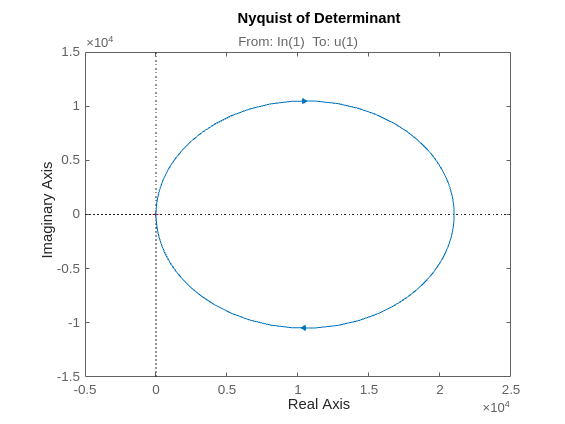


nyquist(det);
title('Nyquist of Determinant')


disp('The generalised controller:');

The generalised controller:


size(MS_C);

State-space model with 2 outputs, 2 inputs, and 8 states.



disp('The generalised plant:');

The generalised plant:


size(P);

State-space model with 6 outputs, 4 inputs, and 8 states.


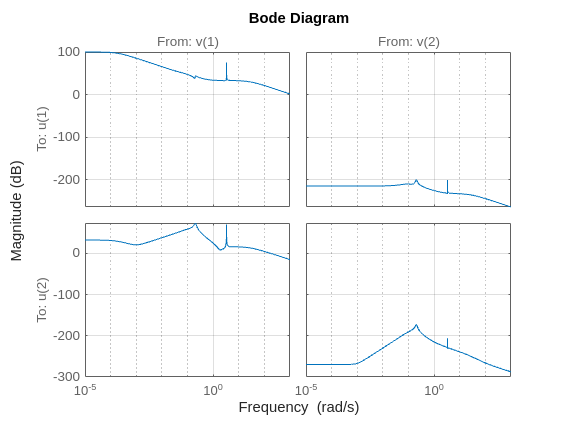


figure
bodemag(MS_C)
grid on


%second plto is inverse notch structure- for fixed structure second element
%should be like this

## 8 Time-domain Simulation

### Reference Tracking

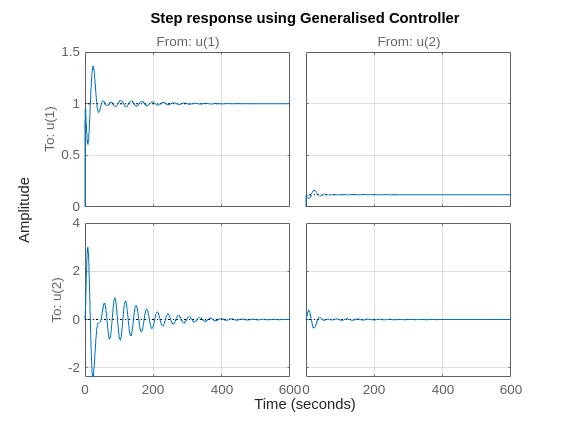

CLstep_hinf = feedback(-MS_C*MIMO_G, eye(2));

[y, tout] = step(CLstep_hinf);

figure
step(CLstep_hinf)
title('Step response using Generalised Controller')
grid on

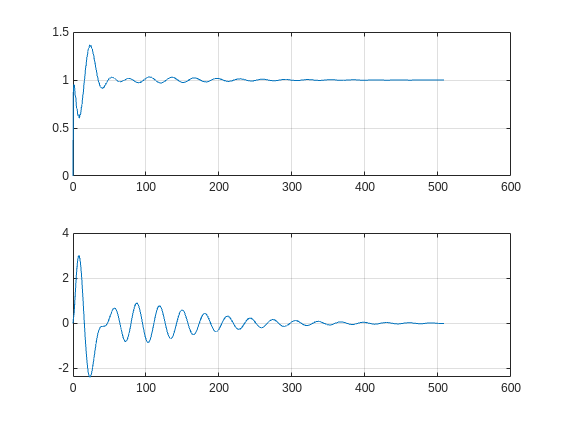


figure
title('Channel 1 only (NAME)')
subplot(2,1,1)
plot(tout, y(:,1,1))
grid on
subplot(2,1,2)
plot(tout, y(:,2,1))
grid on

### Disturbance Rejection

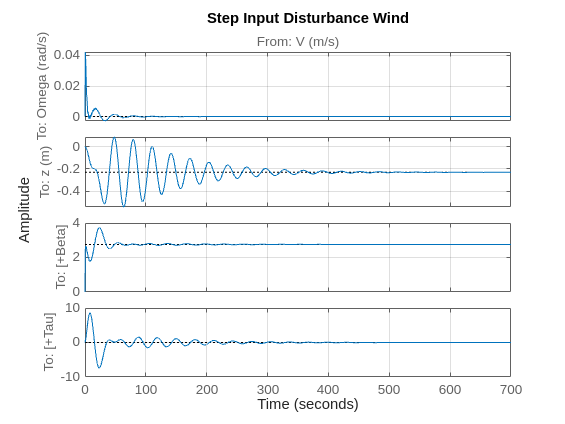

warning off
systemnames ='FWT';   
inputvar ='[V; Beta; Tau]';   
input_to_FWT= '[Beta; Tau; V]';

outputvar= '[FWT; Beta; Tau; FWT]'; 
sysoutname='Gsim';
sysic;
warning on

CL_mimocontroller = minreal(lft(Gsim, MS_C)); % MIMO controller

figure
step(CL_mimocontroller);
title('Step Input Disturbance Wind')
grid on

# Fixed-Structure Control (SISO)

## 2-3. Fixed-Structure Controller Synthesis

Gsiso = FWT(1, 1);

% Fixed Structure SISO controller
s = tf('s');
Kp1 = realp('Kp1',1);
Ki1 = realp('Ki1',1);
Kd1 = realp('Kd1',1); 
Tf1 = realp('Tf1',1);

Kp2 = realp('Kp2',1);
Ki2 = realp('Ki2',1);

Wp_simple = 0.95*(s+0.02*2*pi)/(0.016*pi+s);
C_PID_struct = Kp1+Ki1/s+(Kd1*s)/(Tf1*s+1);
C_PI_struct = Kp2+Ki2/s;

% SISO hinfstruct
Wp_siso = Wp_simple;
Wp_siso.u = 'e'; % On output or on error???
Wp_siso.y = 'z1';

G_siso = -Gsiso;
G_siso.u = 'u';
G_siso.y = 'y';

C_PID_siso = C_PID_struct;
C_PID_siso.u = 'e';
C_PID_siso.y = 'u';

C_PI_siso = C_PI_struct;
C_PI_siso.u = 'e';
C_PI_siso.y = 'u';

Sum1 = sumblk('e = r - y');
Siso_PID_Con = connect(G_siso, Wp_siso, C_PID_siso, Sum1, 'r', 'z1');
Siso_PI_Con = connect(G_siso, Wp_siso, C_PI_siso, Sum1, 'r', 'z1');

opt = hinfstructOptions ('Display', 'final', 'RandomStart', 5);
[N_PID_siso, GAM_PID] = hinfstruct(Siso_PID_Con, opt);

Final: Peak gain = 1.17, Iterations = 47
Final: Peak gain = 1.18, Iterations = 37
Final: Peak gain = 1.16, Iterations = 38
Final: Peak gain = 1.14, Iterations = 54
Final: Peak gain = 1.16, Iterations = 26
Final: Peak gain = 1.18, Iterations = 73


[N_PI_siso, GAM_PI] = hinfstruct(Siso_PI_Con, opt);

Final: Peak gain = 1.27, Iterations = 26
Final: Peak gain = 1.27, Iterations = 28
Final: Peak gain = 1.27, Iterations = 24
Final: Peak gain = 1.27, Iterations = 24
Final: Peak gain = 1.27, Iterations = 29
Final: Peak gain = 1.27, Iterations = 24


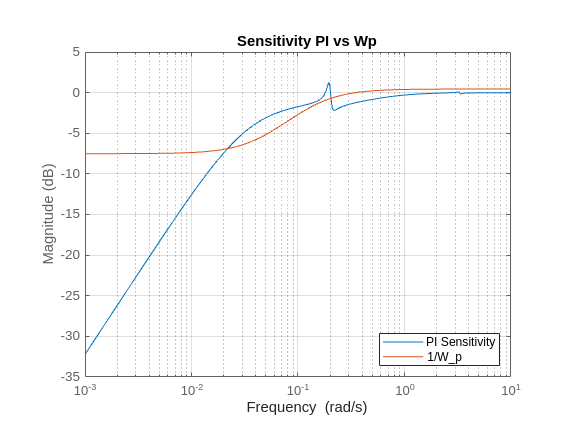


% Extract controller gains :
Kp1_opt = N_PID_siso.Blocks.Kp1.Value;
Ki1_opt = N_PID_siso.Blocks.Ki1.Value;
Kd1_opt = N_PID_siso.Blocks.Kd1.Value;
Tf1_opt = N_PID_siso.Blocks.Tf1.Value;

Kp2_opt = N_PI_siso.Blocks.Kp2.Value;
Ki2_opt = N_PI_siso.Blocks.Ki2.Value;

Kfb_opt_pid = Kp1_opt + Ki1_opt / s +( Kd1_opt * s ) /( Tf1_opt * s +1);
Kfb_opt_pi = Kp2_opt + Ki2_opt / s;

Kfb_opt_pi.u = 'e';
Kfb_opt_pi.y = 'u';

Kfb_opt_pid.u = 'e';
Kfb_opt_pid.y = 'u';

S_pi = 1/ (1 + series(G_siso, Kfb_opt_pi));
S_pid = 1/ (1 + series(G_siso, Kfb_opt_pid));

figure
bodemag(S_pi, 1/Wp_siso)
title('Sensitivity PI vs Wp')
legend('PI Sensitivity', '1/W_p', Location='southeast')
grid on

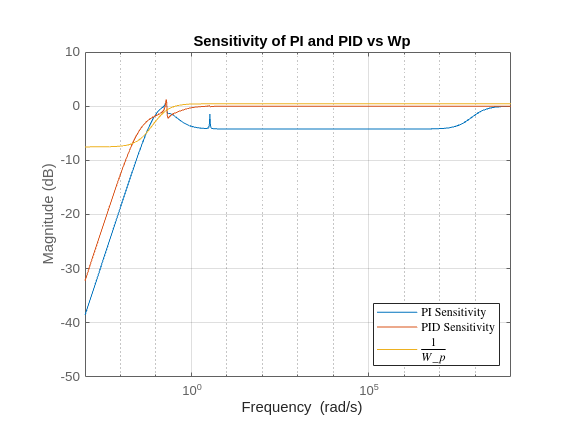


figure
bodemag(S_pid, S_pi, 1/Wp_siso)
title('Sensitivity of PI and PID vs Wp')
legend('PI Sensitivity', 'PID Sensitivity', '$\frac{1}{W_p}$', 'interpreter','latex', Location='southeast')
grid on

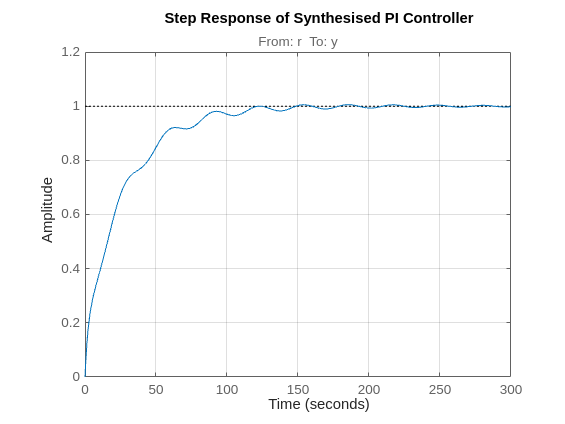


Hpi_SISO_CL = connect(G_siso, Kfb_opt_pi, Sum1, 'r', 'y');
Hpid_SISO_CL = connect(G_siso, Kfb_opt_pid, Sum1, 'r', 'y');

figure
step(Hpi_SISO_CL)
title('Step Response of Synthesised PI Controller')
grid on 


stepinfo(Hpi_SISO_CL)

ans = struct with fields:
         RiseTime: 55.3314
    TransientTime: 113.0651
     SettlingTime: 113.0651
      SettlingMin: 0.9010
      SettlingMax: 1.0057
        Overshoot: 0.5728
       Undershoot: 0
             Peak: 1.0057
         PeakTime: 185.4543


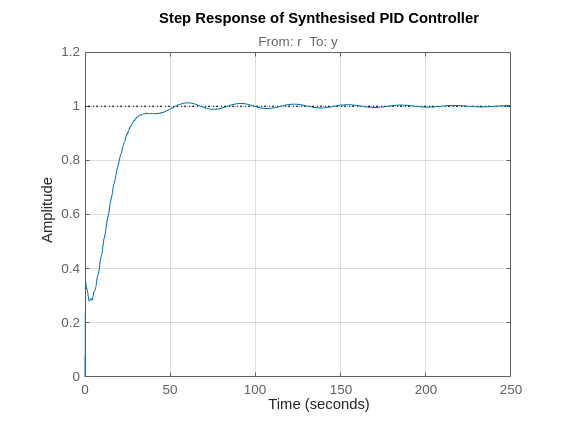


figure
step(Hpid_SISO_CL)
title('Step Response of Synthesised PID Controller')
grid on 


stepinfo(Hpid_SISO_CL)

ans = struct with fields:
         RiseTime: 23.5517
    TransientTime: 31.0709
     SettlingTime: 31.0709
      SettlingMin: 0.9005
      SettlingMax: 1.0120
        Overshoot: 1.2009
       Undershoot: 0
             Peak: 1.0120
         PeakTime: 56.8566


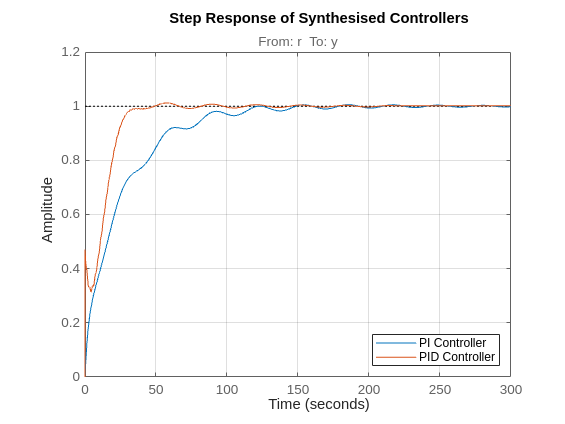


figure
step(Hpi_SISO_CL, Hpid_SISO_CL)
legend('PI Controller', 'PID Controller', Location='southeast')
title('Step Response of Synthesised Controllers')
grid on 


stepinfo(Hpi_SISO_CL)

ans = struct with fields:
         RiseTime: 55.3314
    TransientTime: 113.0651
     SettlingTime: 113.0651
      SettlingMin: 0.9010
      SettlingMax: 1.0057
        Overshoot: 0.5728
       Undershoot: 0
             Peak: 1.0057
         PeakTime: 185.4543


stepinfo(Hpid_SISO_CL)

ans = struct with fields:
         RiseTime: 23.5517
    TransientTime: 31.0709
     SettlingTime: 31.0709
      SettlingMin: 0.9005
      SettlingMax: 1.0120
        Overshoot: 1.2009
       Undershoot: 0
             Peak: 1.0120
         PeakTime: 56.8566


## 4. Comparison synthesised vs manual 

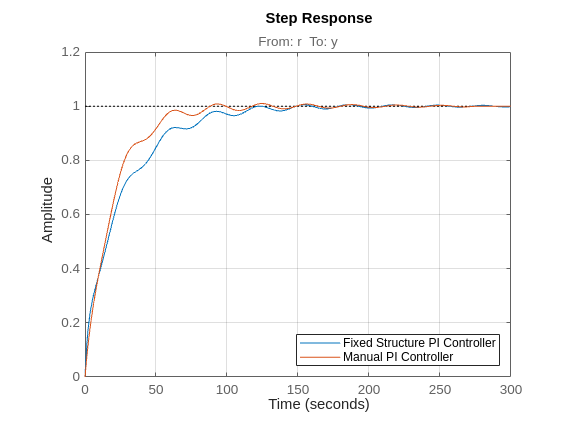

figure
step(Hpi_SISO_CL, SISO_CL)
legend('Fixed Structure PI Controller', 'Manual PI Controller', Location='southeast')
grid on

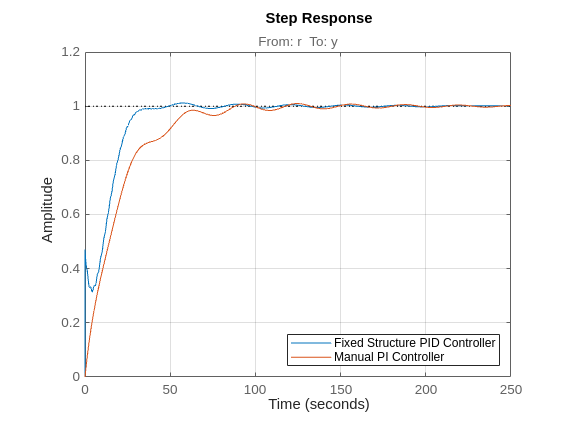


figure
step(Hpid_SISO_CL, SISO_CL)
legend('Fixed Structure PID Controller', 'Manual PI Controller', Location='southeast')
grid on

# Fixed-Structure Control (MIMO)

## 1-3. Fixed-Structure Controller Synthesis

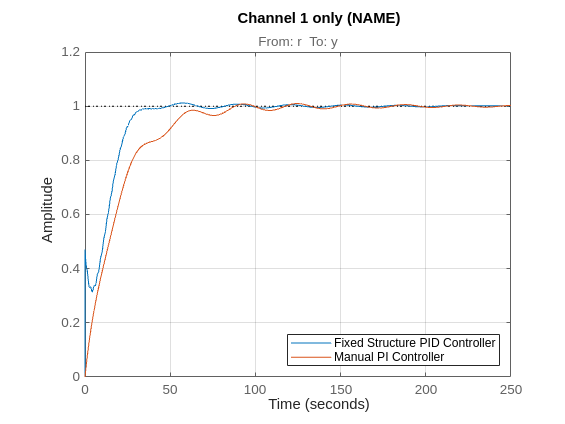

Gmimo = FWT(1:2, 1:2);

Kp3 = realp('Kp3',-3000);
Ki3 = realp('Ki3',210);
% Kd3 = realp('Kd3',1);
% Tf3 = realp('Tf3',1);

% zeta = realp('zeta',1);
% omega = realp('omega',1);

% Define notch filter parameters
wn_z = realp('wn_z', 7.8); 
zeta_z = realp('zeta_z', -27); 
wn_p = realp('wn_p', 0.18); 
zeta_p = realp('zeta_p', -0.05);

wp = [(s/3+0.3*2*pi)/(s+pi*6e-5) 0;
    0 0.05];

wu = [0.005 0;
      0 (0.005*s^2 + 0.0007*s+0.00005)/(s^2 + 0.0014*s + 10e-6)];

C1 = Kp3+Ki3/s;%+(Kd3*s)/(Tf3*s+1);
% C2 = 2*zeta*omega*s/(s^2 + 2*zeta*omega*s + omega^2)
Notch2 = (s^2 + 2*zeta_z*wn_z*s + wn_z^2) / (s^2 + 2*zeta_p*wn_p*s + wn_p^2);

Wp_mimo = wp;
Wp_mimo.u = 'e';
Wp_mimo.y = 'z1';

Wu_mimo = wu;
Wu_mimo.u = 'u';
Wu_mimo.y = 'z2';

G_mimo = -Gmimo;
G_mimo.u = 'u';
G_mimo.y = 'y';

C_mimo = [C1 0; Notch2 0];
C_mimo.u = 'e';
C_mimo.y = 'u';

Sum1 = sumblk('e = r - y',2);
Mimo_Con = connect(G_mimo, Wp_mimo, Wu_mimo, C_mimo, Sum1, 'r', {'z1', 'z2', 'y'});title('Channel 1 only (NAME)')


opt = hinfstructOptions ('Display', 'final', 'RandomStart', 50);
N_mimo = hinfstruct(Mimo_Con, opt);

Final: Peak gain = 4.99, Iterations = 148
Final: Peak gain = 3.71, Iterations = 84
Final: Peak gain = 5.14, Iterations = 148
Final: Peak gain = 3.99, Iterations = 189
Final: Peak gain = 4.99, Iterations = 59
Final: Peak gain = 3.98, Iterations = 141
Final: Peak gain = 3.98, Iterations = 68
Final: Peak gain = 3.98, Iterations = 140
Final: Peak gain = 3.58, Iterations = 165
Final: Peak gain = 3.98, Iterations = 98
Final: Peak gain = 4, Iterations = 104
Final: Peak gain = 3.99, Iterations = 183
Final: Peak gain = 5.13, Iterations = 106
Final: Peak gain = 3.71, Iterations = 115
Final: Peak gain = 3.71, Iterations = 131
Final: Peak gain = 3.99, Iterations = 119
Final: Peak gain = 5.13, Iterations = 116
Final: Peak gain = 4, Iterations = 210
Final: Peak gain = 3.98, Iterations = 276
Final: Peak gain = 3.99, Iterations = 108
Final: Peak gain = 3.99, Iterations = 141
Final: Peak gain = 18.3, Iterations = 102
Final: Peak gain = 3.99, Iterations = 88
Final: Peak gain = 17.2, Iterations = 201
Fin

% Extract controller gains :
Kp3_opt = N_mimo.Blocks.Kp3.Value;title('Channel 1 only (NAME)')
Ki3_opt = N_mimo.Blocks.Ki3.Value;
% Kd3_opt = N_mimo.Blocks.Kd3.Value;
% Tf3_opt = N_mimo.Blocks.Tf3.Value;

% zeta = N_mimo.Blocks.zeta.Value;
% omega = N_mimo.Blocks.omega.Value;

wn_z_opt = N_mimo.Blocks.wn_z.Value;
zeta_z_opt = N_mimo.Blocks.zeta_z.Value;
wn_p_opt = N_mimo.Blocks.wn_p.Value;
zeta_p_opt = N_mimo.Blocks.zeta_p.Value;

Kfb1_opt = Kp3_opt + Ki3_opt / s %+( Kd3_opt * s ) /( Tf3_opt * s +1);

Kfb1_opt =
 
  41.4 s + 3.668
  --------------
        s
 
Continuous-time transfer function.
Model Properties


%Kfb2_opt = 2*zeta*omega*s/(s^2 + 2*zeta*omega*s + omega^2);
notch_opt = (s^2 + 2*zeta_z_opt*wn_z_opt*s + wn_z_opt^2) / (s^2 + 2*zeta_p_opt*wn_p_opt*s + wn_p_opt^2)

notch_opt =
 
   s^2 + 89.12 s + 1.153
  ------------------------
  s^2 - 0.0586 s + 0.04142
 
Continuous-time transfer function.
Model Properties



Kfb_opt = [Kfb1_opt 0; notch_opt 0];

Kfb_opt.u = 'e';
Kfb_opt.y = 'u';

CLsysr = connect(G_mimo, Kfb_opt, Sum1, 'r', 'y');

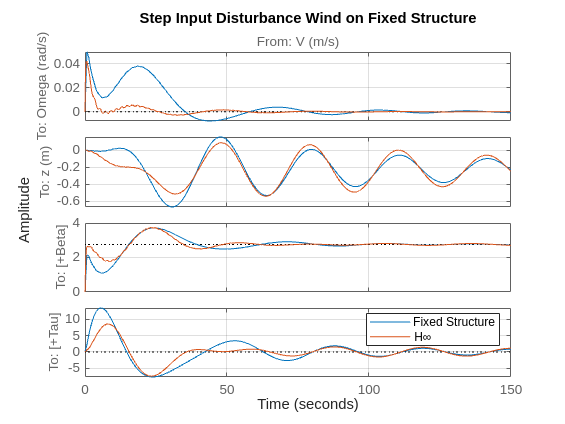

hold on

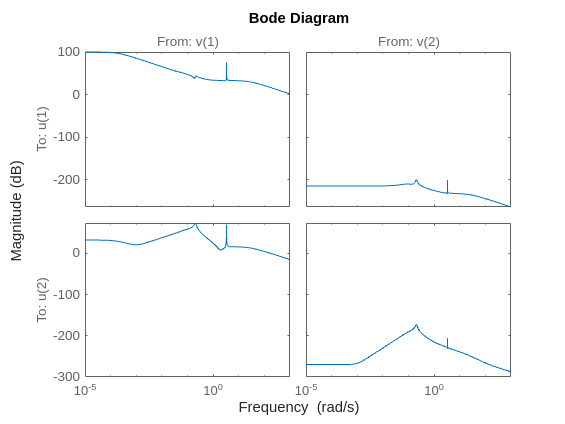

figure
bodemag(MS_C)

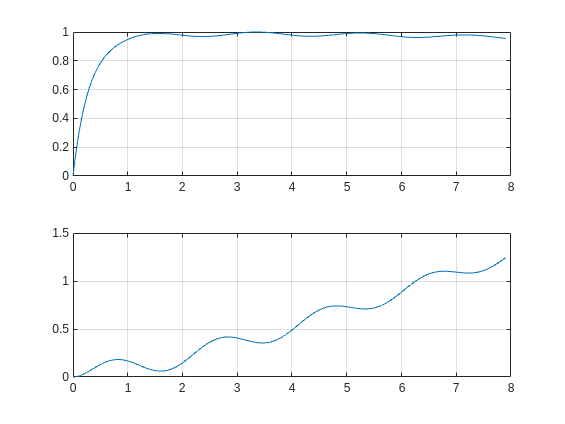

hold on
bodemag(Kfb_opt)


[yout, tout] = step(CLsysr);

figure
title('Channel 1 only (NAME)')
subplot(2,1,1)
plot(tout(1:300), yout(1:300,1,1))

grid on
subplot(2,1,2)
plot(tout(1:300), yout(1:300,2,1))
grid on

**Disturbance Rejection **

warning off
systemnames ='FWT';   
inputvar ='[V; Beta; Tau]';   
input_to_FWT= '[Beta; Tau; V]';

outputvar= '[FWT; Beta; Tau; FWT]'; 
sysoutname='G_mimo';
sysic;
warning on

CLsysd = minreal(lft(G_mimo, Kfb_opt));

## 4. Comparing (Complementary) Sensitivities

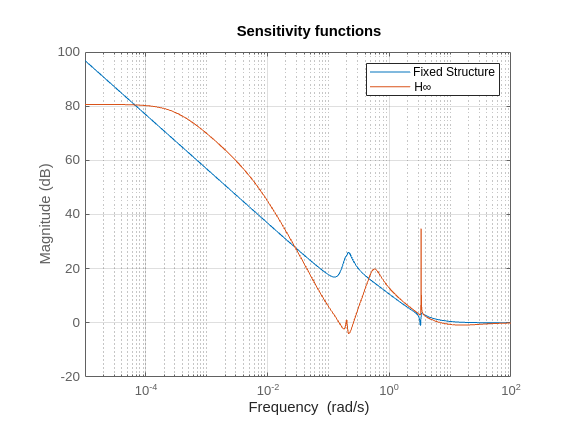

% fixed-structure
[num, denom] = ss2tf(CLsysr.A, CLsysr.B, CLsysr.C, CLsysr.D,1);
tf_fs = tf(num(1,:), denom);

S_fs = 1/(1-tf_fs);
T_fs = 1 - S_fs;

% H_inf 
[num, denom] = ss2tf(CLstep_hinf.A, CLstep_hinf.B, CLstep_hinf.C, CLstep_hinf.D,1);
tf_hinf = tf(num(1,:), denom);

S_hinf = 1/(1-tf_hinf);
T_hinf = 1 - S_hinf;

figure
hold on
bodemag(S_fs)
bodemag(S_hinf)
legend('Fixed Structure','H\infty', Location='northeast')
title('Sensitivity functions')
grid on 

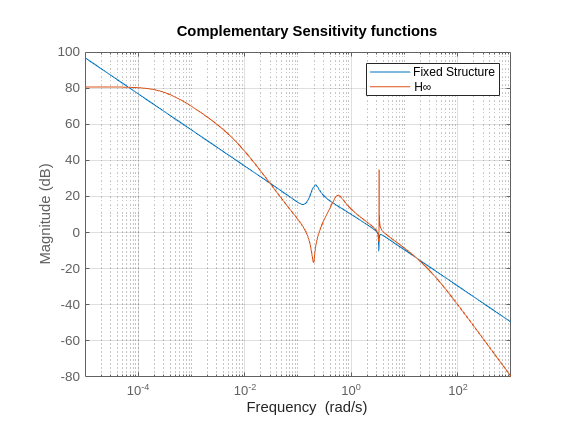


figure
hold on
bodemag(T_fs)
bodemag(T_hinf)
legend('Fixed Structure','H\infty', Location='northeast')
title('Complementary Sensitivity functions')
grid on 

## 5. Comparing $H_\infty$ and Fixed-Structure Controllers 

### Reference Tracking

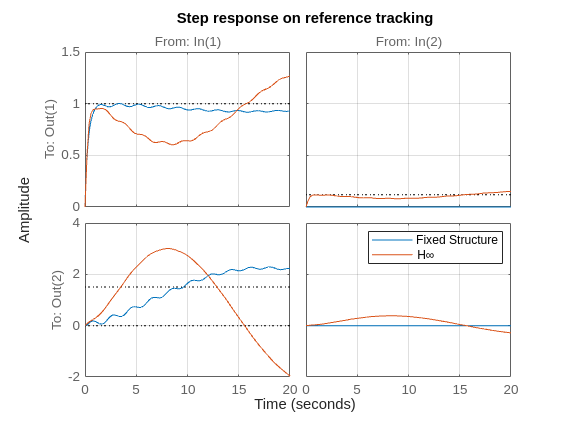

% figure
% step(CLsysr, 600)
% title('Step response of Fixed stucture')
% grid on 

figure
step(CLsysr, CLstep_hinf, 20)
legend('Fixed Structure', 'H\infty')
title('Step response on reference tracking')
grid on

### Disturbance Rejection

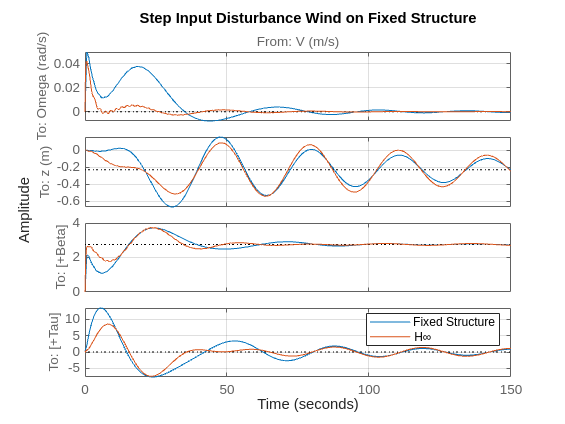

figure
step(CLsysd, CL_mimocontroller, 150);
title('Step Input Disturbance Wind on Fixed Structure')
legend('Fixed Structure', 'H\infty')
grid on


% figure
% step(CL_mimocontroller)
% title('Disturbance Rejection H_\infty controller')
% %legend('Fixed Structure', 'H_\infty')
% grid on